## Hackathon - Team Fast Fingers

The use of the smartphone has been rapidly increasing during the last decade. It has became a necessity nowadays and thus it is an opportunity to maximize the utilization of it for our wellbeing. Creating an app that makes use of the sensors of a smartphone and provides feedback of the progress of a workout or the metrics of a daily activity is something that contributes to this concept to a great extent. 

The goal of this project is to create a program that does what was mentioned before. Specifically the intentive use of this program is to use the sensor data and personal information of the user (gender, age, weight, height etc) to provide information about a workout and its progress, every-day metrics and suggestions on improving the quallity of an exercise.

### Metrics

To operate this program it is required by the user to input some of their personal data, as prompted below:

User Height in centimeters (cm):

Height=181;

User Weight in kilograms (kg):

Weight=90;

User Gender (1 = Male, 2 = Female):

Gender=1;

User Age:

Age=23;

### Number Of Steps 

In order to calculate the total number of steps we use the accelerometer sensor. The XYZ values of the accelerometer are combined to create a new acceleration variable that shows the total movement with any phone orientation. The sampling rate is selected at 10 Hz. We filter the signal using the movmean smoothing function with a window size of 10. From the filtered signal we take the peaks which equal the number of steps taken and we filter is once more using the same function to aquire the intensity of the movement.

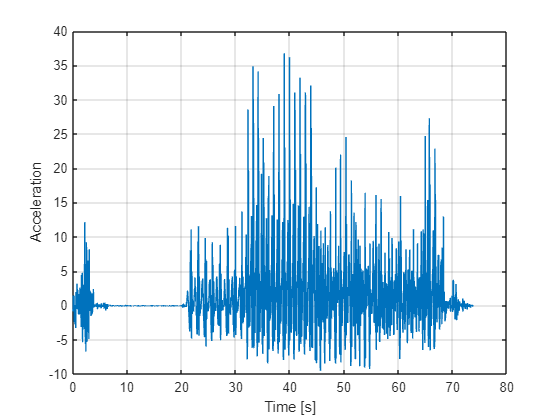

referenceTimestamp = Acceleration.Timestamp(1);
referenceSerialDateNum = datenum(referenceTimestamp);

for i = 1:numel(Acceleration.Timestamp)
serialDateNum = datenum(Acceleration.Timestamp(i));
seconds(i) = (serialDateNum - referenceSerialDateNum) * 24 * 60 * 60;
end

acc = table2array(Acceleration);
comb(:,1) = sqrt((acc(:,1)).^2 + (acc(:,2)).^2 + (acc(:,3)).^2 )-10;

plot(seconds,comb)
grid on
xlabel('Time [s]') 
ylabel('Acceleration') 

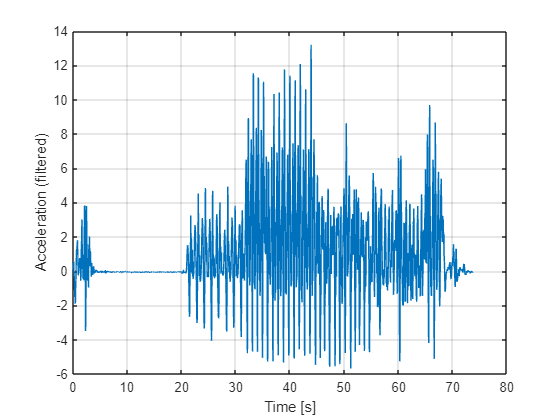

samplingRate = 10;
accelData = comb; 
minDistance = 10; 
windowSize = 10;
accelDataFiltered = movmean(accelData, windowSize);
[peaks, peakLocs] = findpeaks(accelDataFiltered, 'MinPeakHeight', threshold, 'MinPeakDistance', minDistance);
numSteps = numel(peaks);
plot(seconds,accelDataFiltered)
grid on
xlabel('Time [s]') 
ylabel('Acceleration (filtered)') 

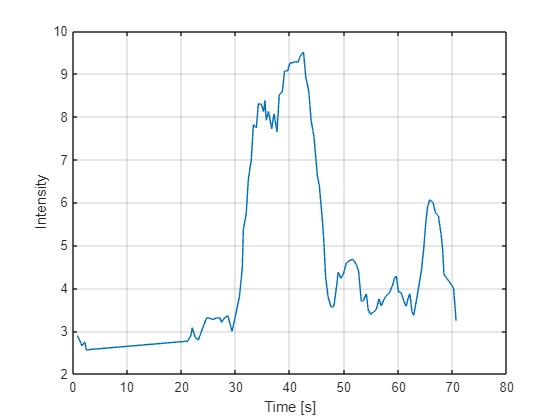

numSteps = numel(peaks);
for j=1:numSteps
    peakLocse(j)=seconds(peakLocs(j));
end
plot(peakLocse,inten)
grid on
xlabel('Time [s]') 
ylabel('Intensity') 


[peaks, peakLocs] = findpeaks(accelDataFiltered, 'MinPeakHeight', threshold, 'MinPeakDistance', minDistance);
NoSteps = numel(peaks);

disp(['Number of steps: ', num2str(NoSteps)]);

Number of steps: 109


### Distance traveled 

Using the height of the user and the number of steps we can calculate the total distance traveled. Approximately the distance covered in one stride is 0.41 times the height of the person, so the total distance traveled in meters is:

H_Sratio=0.41;
DistanceTraveled=H_Sratio*Height*NoSteps/100;

We can also test the accuracy of the approximation using the gps data from the example model, as shown below:

In this example, latitude and longitude have been stored into variable names *lat* and *lon* respectively. The first step in using these to calculate distance is to declare a couple of variables: one will represent the circumference of the earth in miles, the other will represent the total distance traveled, which will be set to zero for now.

earthCirc = 24901;
totaldis = 0;

To solve this problem, calculations will have to be repeated several times in a loop. Because of this, we use a function called a [`for loop`](https://www.mathworks.com/help/matlab/ref/for.html) which will repeat a block of code *for* a specified number of times. In this case, we want to have it run until the end of our vector of data. The [`length`](https://www.mathworks.com/help/matlab/ref/length.html) command can be used to determine the number of elements in a vector and therefore how many times we need to run the loop. When solving for the difference in position, one position and the next position are used at the same time, so we need to stop one before the end of the vector as seen below. If this isn't done, we will get an error because we will be trying to acces data from outside of the vector.

for i = 1:(length(Position.latitude)-1)

Now we save the first position and the second position into variables. We will do this using the variable *i* from above. This variable is a vector from 1 to the end of our latitude vector which can be used to index the latitude and longitude vectors.

    lat1 = Position.latitude(i);     % The first latitude
    lat2 = Position.latitude(i+1);   % The second latitude
    lon1 = Position.longitude(i);     % The first longitude
    lon2 = Position.longitude(i+1);   % The second longitude

Thankfully for us, MATLAB has a command [`distance`](https://www.mathworks.com/help/map/ref/distance.html) that calculates distance when given latitude and longitude. This will give us the difference in degrees which we will then turn into length by creating equivalent fractions:


$$\frac{\textrm{traveledDistance}}{\textrm{earth'sCircumference}}=\frac{\textrm{degreesTraveled}}{\textrm{earth'sDegrees}}\;$$


From this we solve for 'traveledDistance'. We will use 360 for 'earth’sDegrees' because that is the total number of degrees in a circle. While the earth is not a perfect circle, this will still be a good estimation

    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;

Now we add up the distance and store it into the *totaldis* variable. What this code will do is take the previous total distance and add the distance just calculated onto it. With this, we have calculated everything that we needed to within the for loop and must close the loop by using the [`end`](https://www.mathworks.com/help/matlab/ref/end.html) command. Then we calcultate the total distance and the steps taken as shown below:

    totaldis = totaldis + dis;
end
stride = H_Sratio*Height/100;          % Average stride (m)
totaldis_km = totaldis*1.60934;    % Converting distance from miles to km
steps = totaldis_km*1000/stride;

We can now compare the two calculations and find the proper value for the approximation from the average values of the steps taken and total distance.

Mean_Steps=(steps+NoSteps)/2;
Mean_TotDist=(totaldis_km*1000+DistanceTraveled)/2;

H_Sratio=Mean_TotDist/(Mean_Steps*Height/100);
disp(['Approximation correction ', num2str(H_Sratio)])

Approximation correction 0.41


disp(['The total distance traveled is: ', num2str(Mean_TotDist),' meters'])

The total distance traveled is: 48.5362 meters


disp(['You took ', num2str(Mean_Steps) ' steps'])

You took 65.4039 steps


### Height Measurment

With the use of the GPS measurements we can calculate the height difference the user traveled while climbing a flight of stairs or walking on an inclined road. The data are used later on, to calculate the intensity.

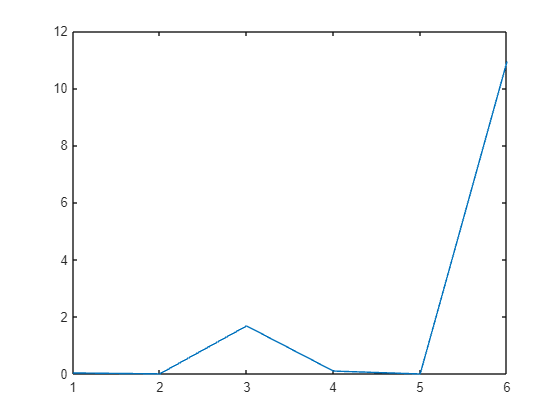

pos = table2array(Position);
alt = pos(:,3);
dx = zeros(height(pos)-1,1);
for i = 2 : height(pos)
dx(i-1,1) = abs(alt(i) - alt(i-1));
end

plot(dx)

Now we can determine the threshold of the elevation over which the intensity differs

Elev_thresh=5;

### Workout Intensity

From the data aquired from the accelerometer we can the analysis from the expirements we can figure out the intensity of the person's workout and the thresholds between the three main categories (standing still, walking, running - climbing).

plot(peakLocse,inten)
grid on
xlabel('Time [s]') 
ylabel('Intensity') 

We can now determine the thresholds for the intensity measurements for the analysis below:

Int_thresh1=3; %under = standing still
Int_thresh2=6; %over = running

### Calories Burnt

We can calculate the calories burnt during an exercise from the body weight of the person, the intensity and the duration of the exercise. 


$$\mathrm{Calories}=\frac{\mathrm{Time}\cdot \mathrm{MET}\cdot \mathrm{Body}\;\mathrm{Weight}}{200}$$


The Metabolic Equivalent of Tasks (MET) metric is used to measure the level of intensity of an exercise refering to the oxygen consumption during the task. Using the referense values of three types of tasks (more on [Compedium of Physical Activities](https://sites.google.com/site/compendiumofphysicalactivities/home) website), as shown below, we can calculate the calories burnt during the task.

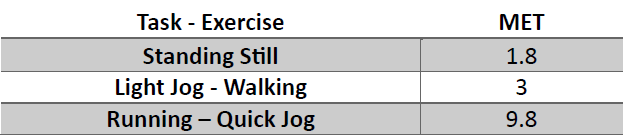

During the test we can calculate the calories burnt per task and in total using the previous formula and exchanging the values for the MET depending on the task intensity.

MET=1.8;
calories=0;
Time=2;

for i=1:length(inten)
    if inten(i)>Int_thresh2 || dx(end)>Elev_thresh    %check for intensity level type running or if the user is climbing
        MET=9.8;
    elseif inten(i)<Int_thresh1    %check for intensity level type standing still
        MET=1.8;
    else 
        MET=3;
    end

    calories=calories+(Time*MET*Weight/200);
end

### Basic Metabolic Rate (BMR) and Remaining Calories

Finaly using the data aquired from the user we can calculate the BMR metric, which represents the daily calorie intake for a human to just rest and do nothing. The BMR is calculated using the formulas (**Revised Harris-Benedict Equation)** below, using the gender, weight, height and age of the user.


$$\mathrm{MEN}\;\mathrm{BMR}=13\ldotp 397\cdot \mathrm{Weight}+4\ldotp 799\cdot \mathrm{Height}-5\ldotp 677\cdot \mathrm{Age}+88\ldotp 362$$



$$\mathrm{WOMEN}\;\mathrm{BMR}=9\ldotp 247\cdot \mathrm{Weight}+3\ldotp 098\cdot \mathrm{Height}-4\ldotp 330\cdot \mathrm{Age}+447\ldotp 593$$


Knowing the BMR and calories burnt in a day we can now calculate the basic amount of calories the user needs to intake so that he stays at the same weight. 

if Gender==1
    BMR=13.397*Weight + 4.799*Height - 5.677*Age + 88.362;
else
    BMR = 9.247*Weight + 3.098*Height - 4.330*Age + 447.593;
end
disp(['The BMR of the user is ', num2str(BMR),' calories'])

The BMR of the user is 2032.14 calories


Tot_cals=BMR+calories;
disp(['The optimal calorie intake is ', num2str(Tot_cals),' calories'])

The optimal calorie intake is 2993.52 calories
